# Thermoeconomic Analysis of a ORC plant

This Live Script makes a Thermoeconomic Analysis of an Organic Rankine Cycle, using the TaesLab functions.

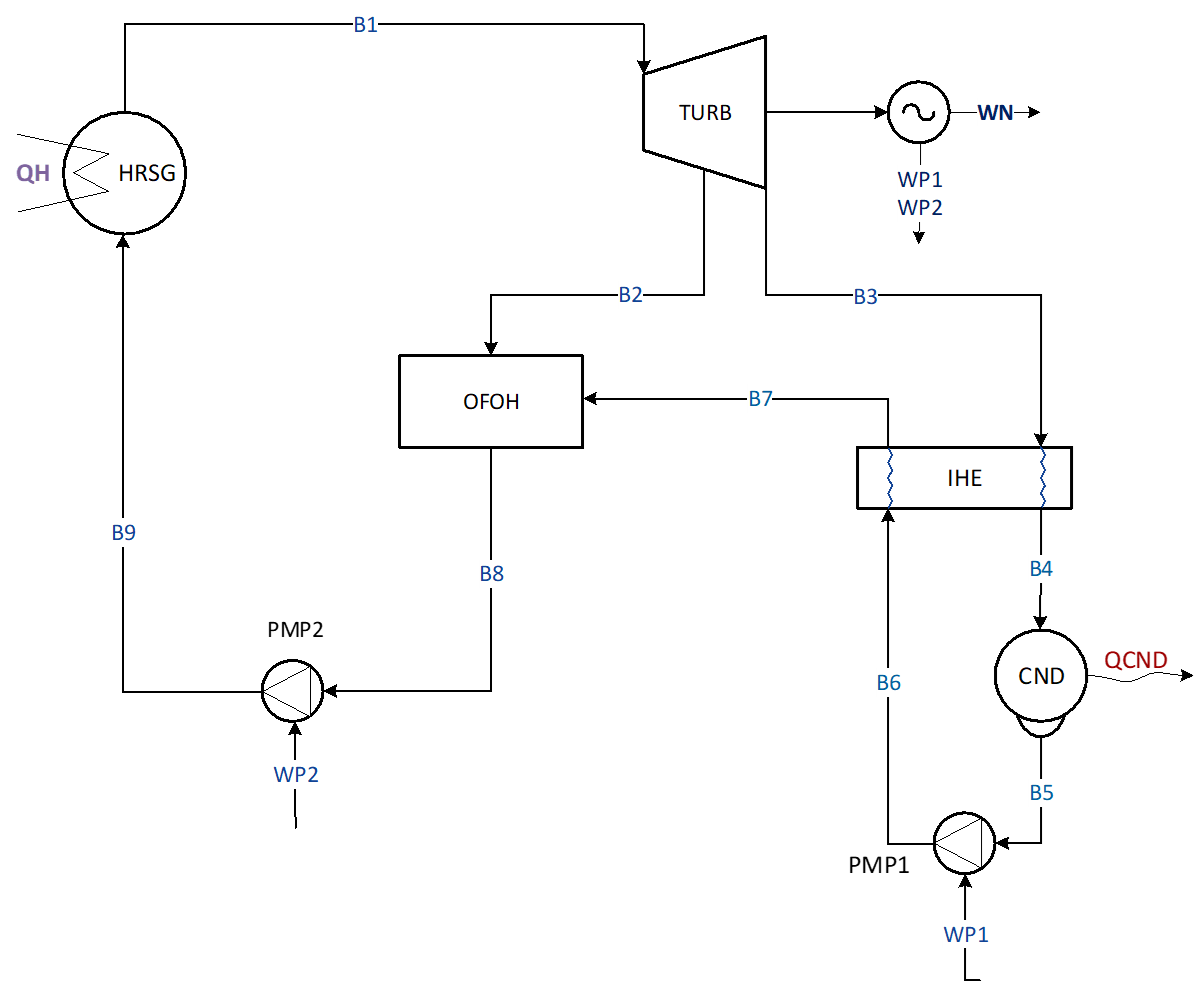

#### 1. Read the data model file

This function read the data model file and load it as a MATLAB object 

model=ThermoeconomicModel('ORC_model.xlsx');

INFO: cDataModel. Productive Structure is valid
INFO: cDataModel. Format Definition is valid
INFO: cDataModel. Exergy values [REF] are valid
INFO: cDataModel. Exergy values [Eta_TRB] are valid
INFO: cDataModel. Exergy values [Eta_IHE] are valid
INFO: cDataModel. Exergy values [Eta_PMP] are valid
INFO: cDataModel. Exergy values [Pinch_15] are valid
INFO: cDataModel. Exergy values [P_PE] are valid
INFO: cDataModel. Exergy values [P_SE] are valid
INFO: cDataModel. Waste Definition is valid
INFO: cDataModel. No Resources Cost Data available
INFO: cDataModel. Data model ORC_model is valid
INFO: cThermoeconomicModel. Productive Diagram Active
INFO: cThermoeconomicModel. Set state REF
INFO: cThermoeconomicModel. Compute Diagram FP
INFO: cThermoeconomicModel. Compute thermoeconomic analysis for state REF
INFO: cThermoeconomicModel. Thermoeconomic diagnosis is not activated
INFO: cThermoeconomicModel. Recycle is not active
INFO: cThermoeconomicModel. Summary mode is NONE


setDebug(model,false);

#### 2. Show results for the REF case

Show the processes efficiency table

showResults(model,'eprocesses');


Processes Exergy Table - REF

Key          F(KW)       P(KW)       I(KW)      k(J/J)      η (%)
——————————————————————————————————————————————————————————————————
TURB        65.466      53.810      11.656      1.2166      82.20
ALT         53.810      52.731       1.079      1.0205      97.99
OFOH        15.685      14.870       0.815      1.0548      94.80
IHE          1.870       1.355       0.515      1.3801      72.46
CND          8.896       8.896       0.000      1.0000     100.00
PMP1         0.505       0.432       0.073      1.1685      85.58
PMP2         2.226       1.940       0.286      1.1474      87.15
HRSG        87.810      73.320      14.490      1.1976      83.50
ENV         87.810      50.000      37.810      1.7562      56.94



Show the exergy cost of flows (table *dfcost*)

`Cost are decomposed into the part due to internal irreversibilities (kin*) and the cost due to wastes (kr*)`

showResults(model,'dfcost');


Flows Exergy Cost - REF

Key          B(KW)      B*(KW)    Bin*(KW)     Br*(KW)     k*(J/J)   kin*(J/J)    kr*(J/J)
———————————————————————————————————————————————————————————————————————————————————————————
QH          87.810      87.810      87.810       0.000      1.0000      1.0000      0.0000
B1          90.130     127.495     111.514      15.981      1.4146      1.2373      0.1773
B2           8.734      12.355      10.806       1.549      1.4146      1.2373      0.1773
B3          15.930      22.534      19.709       2.825      1.4146      1.2373      0.1773
B4          14.060      19.889      17.396       2.493      1.4146      1.2373      0.1773
B5           5.164       7.305       6.389       0.916      1.4146      1.2373      0.1773
B6           5.596       8.191       7.165       1.027      1.4638      1.2803      0.1835
B7           6.951      10.837       9.478       1.358      1.5590      1.3636      0.1954
B8          14.870      23.191      20.284       2.907      1.5

Show the irreversibilty-cost graph (table* dict*)

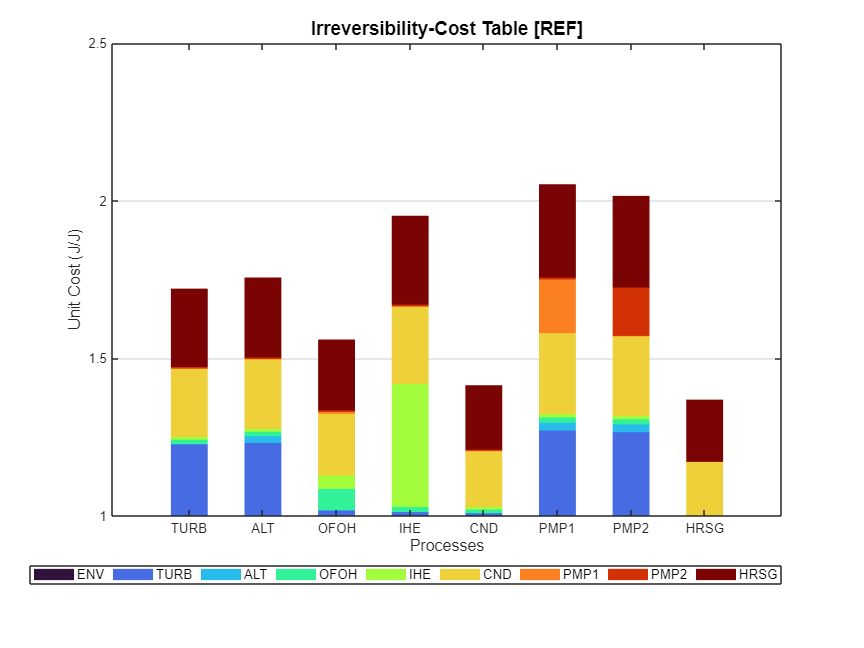

showGraph(model,'dict');

`This graph shows the cost of processes and the contribution of the irreversibilities of each process.`

#### 3. Compare the different plant simulations

Show the exergy cost of flows (table *dfuc*)

setSummary(model,'STATES');
showResults(model,'dfuc');


Flows Direct Unit Exergy Cost (J/J) - SUMMARY

 key            REF    Eta_TRB    Eta_IHE    Eta_PMP   Pinch_15       P_PE       P_SE
——————————————————————————————————————————————————————————————————————————————————————
 QH          1.0000     1.0000     1.0000     1.0000     1.0000     1.0000     1.0000
 B1          1.4146     1.4303     1.4207     1.4237     1.4529     1.4910     1.6035
 B2          1.4146     1.4303     1.4207     1.4237     1.4529     1.4910     1.6035
 B3          1.4146     1.4303     1.4207     1.4237     1.4529     1.4910     1.6035
 B4          1.4146     1.4303     1.4207     1.4237     1.4529     1.4910     1.6035
 B5          1.4146     1.4303     1.4207     1.4237     1.4529     1.4910     1.6035
 B6          1.4638     1.5002     1.4702     1.4938     1.5035     1.5427     1.6438
 B7          1.5590     1.6266     1.5841     1.5851     1.6012     1.6437     1.7102
 B8          1.5596     1.5881     1.5861     1.5769     1.6019     1.7978     1.6881
 B9  

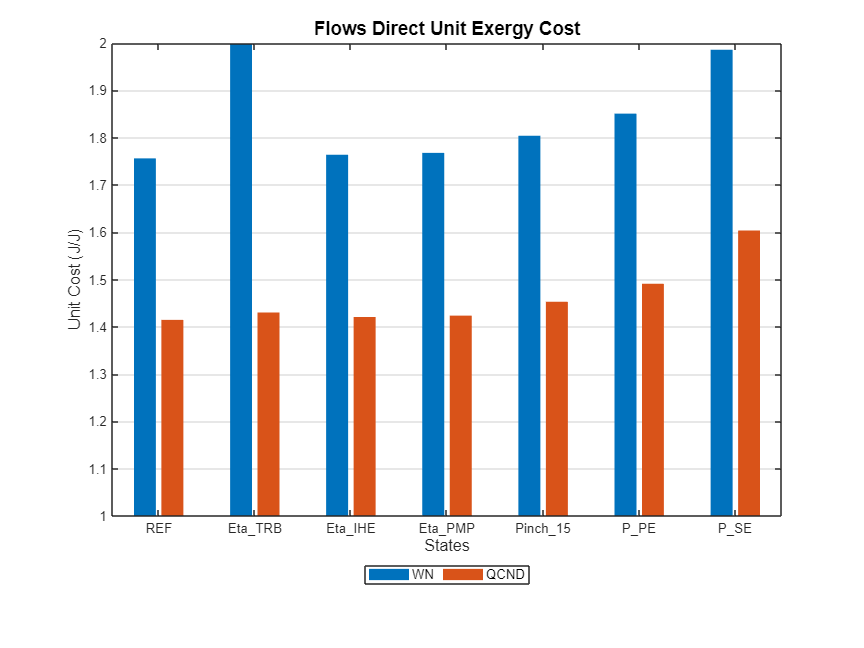

showGraph(model,'dfuc');

#### 4. Compare States. Thermoeconomic Diagnosis

Compare REF state with P_SE (Increase the low pressure and condenser temperature)

setState(model,'P_SE');
summaryDiagnosis(model);

Fuel Impact:         11.4800 (KW)
Technical Saving:    11.4800 (KW)



showResults(model,'dgn');


Diagnosis Summary - P_SE

Key         MF(KW)      ΔI(KW)      ΔR(KW)     ΔPt(KW)     MF*(KW)     MR*(KW)    ΔPt*(KW)
———————————————————————————————————————————————————————————————————————————————————————————
TURB       -0.1581     -0.0940      0.0000      0.0000     -0.1943      0.0000      0.0000
ALT        -0.0059      0.0002      0.0000      0.0000     -0.0088      0.0000      0.0000
OFOH       -0.6134     -0.5870      0.0000      0.0000     -0.6249      0.0000      0.0000
IHE        -0.2253     -0.0500      0.0000      0.0000     -0.2759      0.0000      0.0000
CND         0.0000      0.0000     10.2610      0.0000     -0.0001     12.5662      0.0000
PMP1       -0.0028     -0.0012      0.0000      0.0000     -0.0043      0.0000      0.0000
PMP2        0.0037      0.0410      0.0000      0.0000      0.0056      0.0000      0.0000
HRSG        0.0166      1.9100      0.0000      0.0000      0.0166      0.0000      0.0000
ENV        -0.9853      1.2190     10.2610      0.0000     -1.

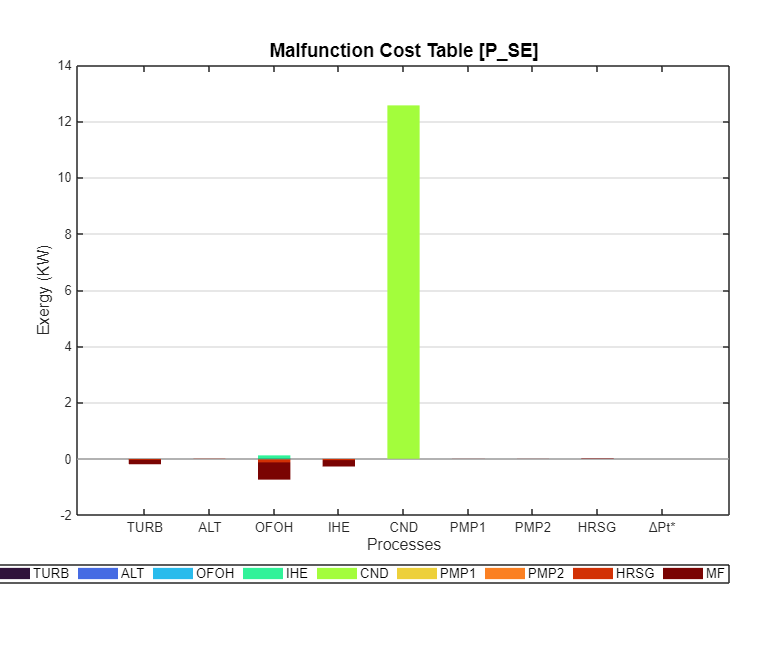

showGraph(model,'mfc');

`In this case we consumed 11.48 kW of additional resources due mainly to the condenser losses.`

#### 5. Analize Recycling Condenser Heat

Define the active waste and analyze the recycling (table *rad*)

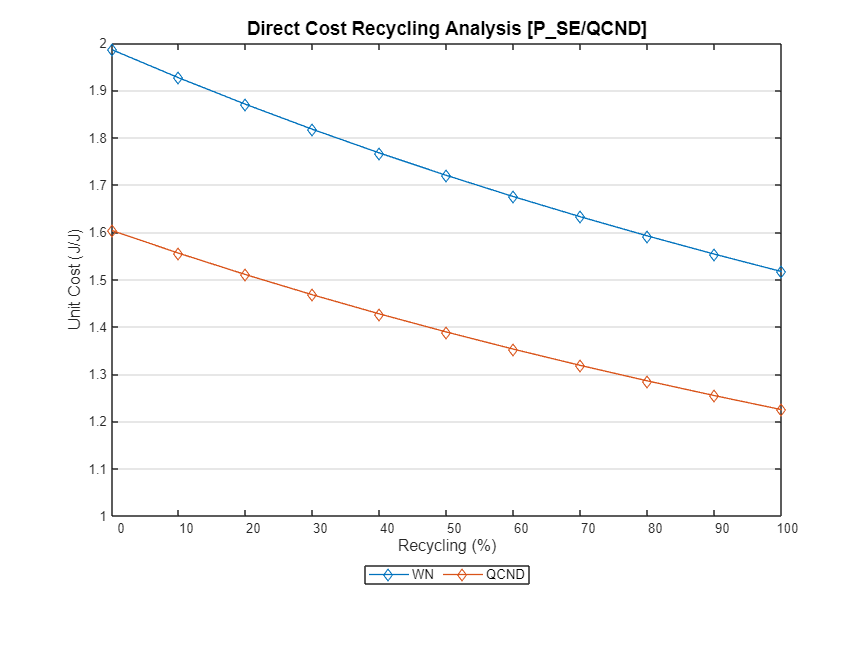

setActiveWaste(model,'QCND');
setRecycling(model,true);
showGraph(model,'rad');

`Comparing with the unit cost of electricity (WN) in the REF state, if we recycled more than the 50% of heat, electricity cost is cheaper.`

setWasteRecycled(model,0.5);
summaryDiagnosis(model);

Fuel Impact:         11.4800 (KW)
Technical Saving:    -2.0694 (KW)



showResults(model,'dgn');


Diagnosis Summary - P_SE

Key         MF(KW)      ΔI(KW)      ΔR(KW)     ΔPt(KW)     MF*(KW)     MR*(KW)    ΔPt*(KW)
———————————————————————————————————————————————————————————————————————————————————————————
TURB       -0.1581     -0.0940      0.0000      0.0000     -0.1943      0.0000      0.0000
ALT        -0.0059      0.0002      0.0000      0.0000     -0.0088      0.0000      0.0000
OFOH       -0.6134     -0.5870      0.0000      0.0000     -0.6249      0.0000      0.0000
IHE        -0.2253     -0.0500      0.0000      0.0000     -0.2759      0.0000      0.0000
CND         0.0000      0.0000      0.6825      9.5785     -0.0001     -0.7357     13.3019
PMP1       -0.0028     -0.0012      0.0000      0.0000     -0.0043      0.0000      0.0000
PMP2        0.0037      0.0410      0.0000      0.0000      0.0056      0.0000      0.0000
HRSG        0.0166      1.9100      0.0000      0.0000      0.0166      0.0000      0.0000
ENV        -0.9853      1.2190      0.6825      9.5785     -1.

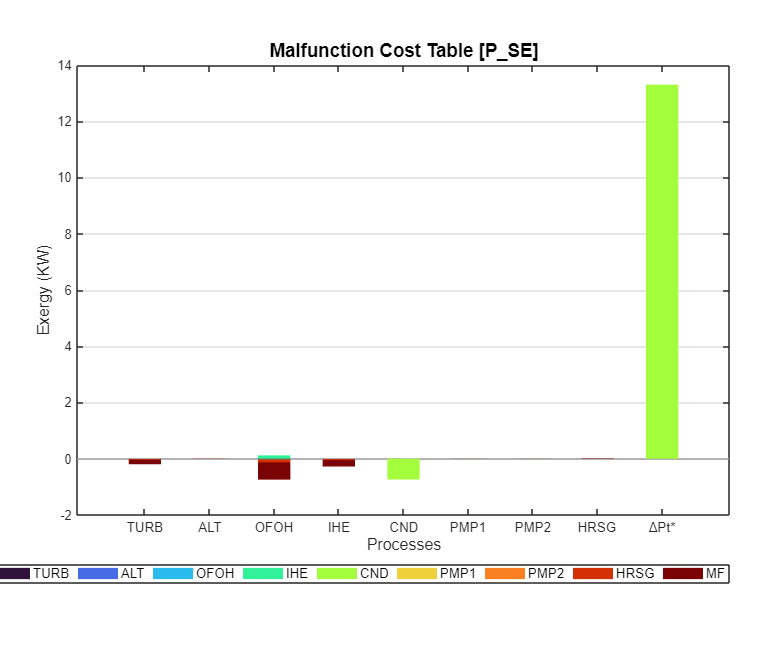

showGraph(model,'mfc');

`We consume 11.48 kW of additional resources, but producing 9.5 kW of additional heat. There is a technical saving of 2.07 kW`